# Sequence-to-Sequence Classification Using 1-D Convolutions

This example shows how to classify each time step of sequence data using a generic temporal convolutional network (TCN).

PRJ: see also NN models published here: [https://paperswithcode.com/paper/eegnet-a-compact-convolutional-network-for](https://paperswithcode.com/paper/eegnet-a-compact-convolutional-network-for) 

clear all; close all;

## Loading all the data

elToConsider = {'Cz';'C3';'C4'};

Data organization and splitting into training/validation/testing:

[InTrain, OutTrain] = loadData('../data/eyes/TrainTest/train', elToConsider);
% [InValid, OutValid] = loadData('../data/eyes/TrainValidTest/valid', elToConsider);
[InTest, OutTest]   = loadData('../data/eyes/TrainTest/test', elToConsider);

Divide data randomly into **train**, **test** and **validation** datasets

%PRJ - todo: load all data first and then divide it using 'dividerand' to
%define train, test and validation datasets

% nChunks=numel(Outputs);
% [trainInd,valInd,testInd] = dividerand(nChunks,0.8,0,0.2); % remove validation proportion
%  
% InTrain = Inputs(1,trainInd);
% OutTrain= Outputs(1,trainInd);
% % InValid = Inputs(1,valInd);
% % OutValid= Outputs(1,valInd);
% InTest  = Inputs(1,testInd);
% OutTest= Outputs(1,testInd);


Adopt the network to the **Seq-to-Label**:

OutTrain = SeqToLabel(OutTrain);
% OutValid = SeqToLabel(OutValid);
OutTest = SeqToLabel(OutTest);

## Define Deep Learning Model

layers = [
    sequenceInputLayer(3,"Name","input")
    lstmLayer(128,"Name","lstm","OutputMode","last")
    dropoutLayer(0.5,"Name","dropout")
    fullyConnectedLayer(2,"Name","fc")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classification")];

lgraph = layerGraph(layers);

View the network in a plot.

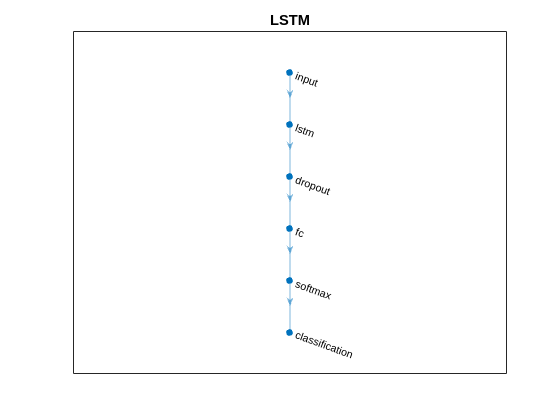

figure
plot(lgraph)
title("LSTM")

## Specify Training Options

Specify a set of options used for training.

- Train for 60 epochs with a mini-batch size of 1.

- Train with a learning rate of 0.001.

- Display the training progress in a plot and suppress the verbose output.

options = trainingOptions("adam", ...
    MaxEpochs=500, ...
    miniBatchSize=50, ...
    Plots="training-progress", ...
    Verbose=true);

% options = trainingOptions("adam", ...
%     MaxEpochs=500, ...
%     miniBatchSize=50, ...
%     ValidationData={InValid,OutValid}, ...
%     ValidationFrequency=100, ...
%     Plots="training-progress", ...
%     Verbose=true);

## Train Model

Training on single GPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:02 |       40.00% |       0.7480 |          0.0010 |
|       5 |          50 |       00:00:05 |       58.00% |       0.8729 |          0.0010 |
|      10 |         100 |       00:00:08 |       38.00% |       0.9030 |          0.0010 |
|      14 |         150 |       00:00:11 |       50.00% |       0.7705 |          0.0010 |
|      19 |         200 |       00:00:13 |       54.00% |       0.6830 |          0.0010 |
|      23 |         250 |       00:00:16 |       70.00% |       0.6320 |          0.0010 |
|      28 |         300 |       00:00:18 |       50.00% |       0.

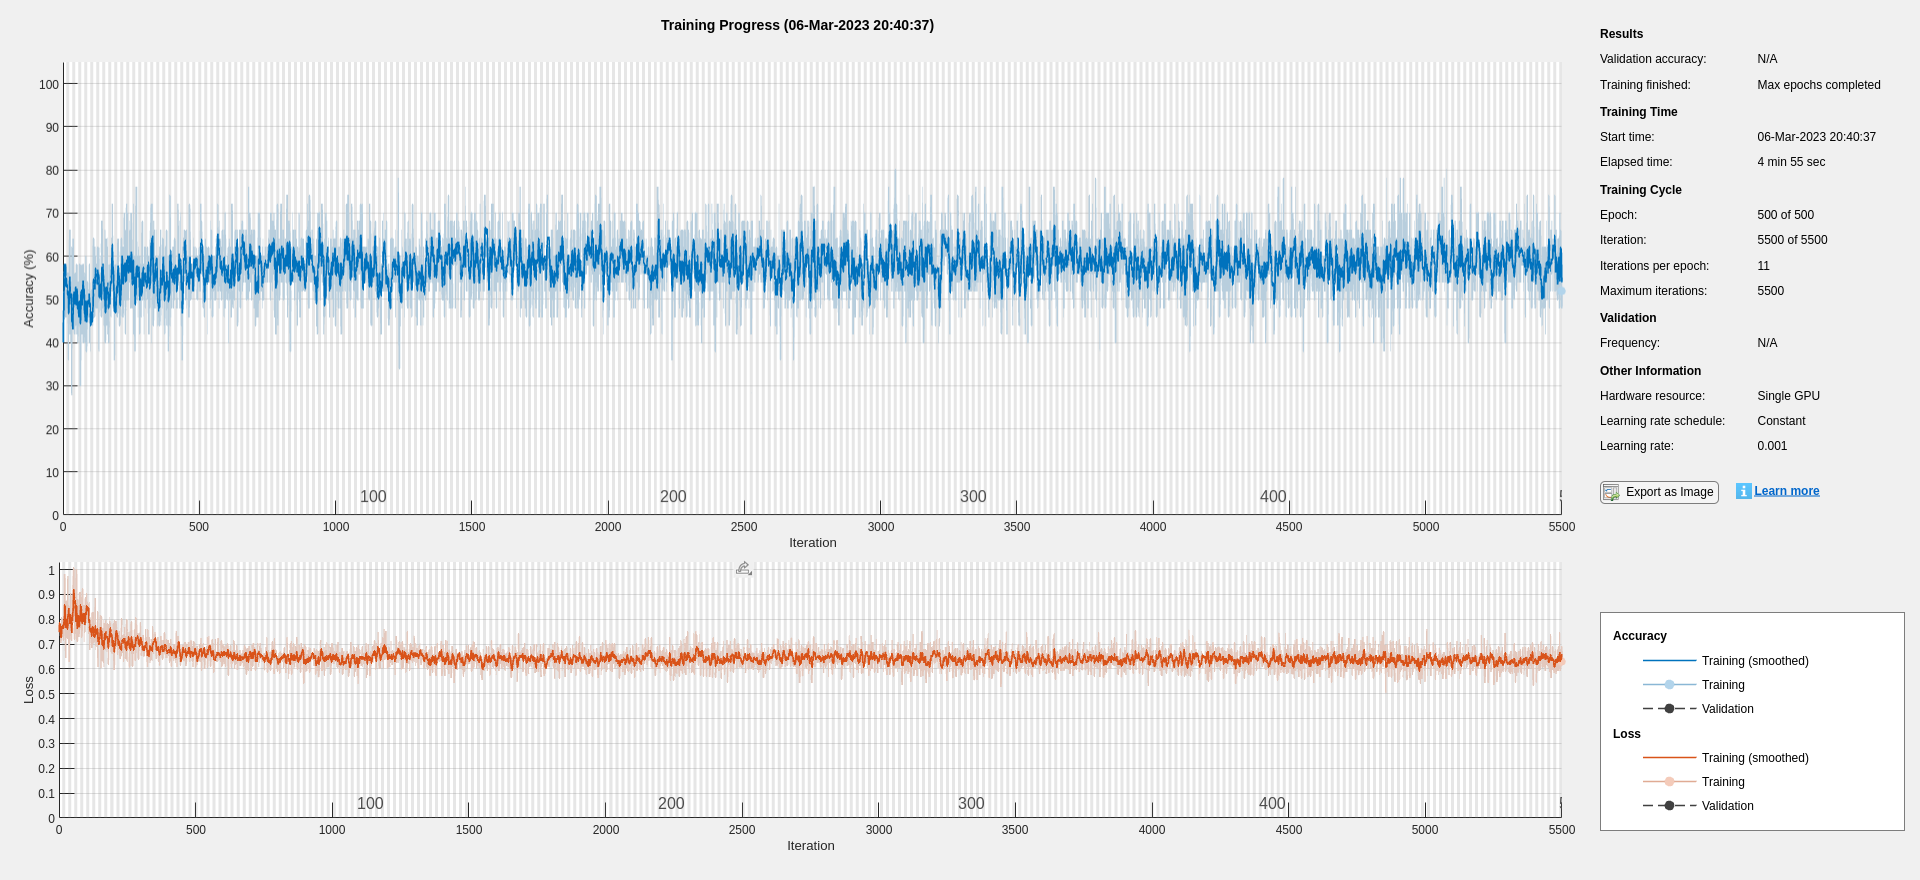

net = trainNetwork(InTrain,OutTrain,lgraph,options);

## Train more

Training on single GPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:01 |       62.00% |       0.5829 |          0.0010 |
|       5 |          50 |       00:00:04 |       46.00% |       1.3560 |          0.0010 |
|      10 |         100 |       00:00:06 |       52.00% |       0.8877 |          0.0010 |
|      14 |         150 |       00:00:09 |       50.00% |       0.8670 |          0.0010 |
|      19 |         200 |       00:00:11 |       54.00% |       0.7226 |          0.0010 |
|      23 |         250 |       00:00:14 |       50.00% |       0.8160 |          0.0010 |
|      28 |         300 |       00:00:16 |       40.00% |       0.

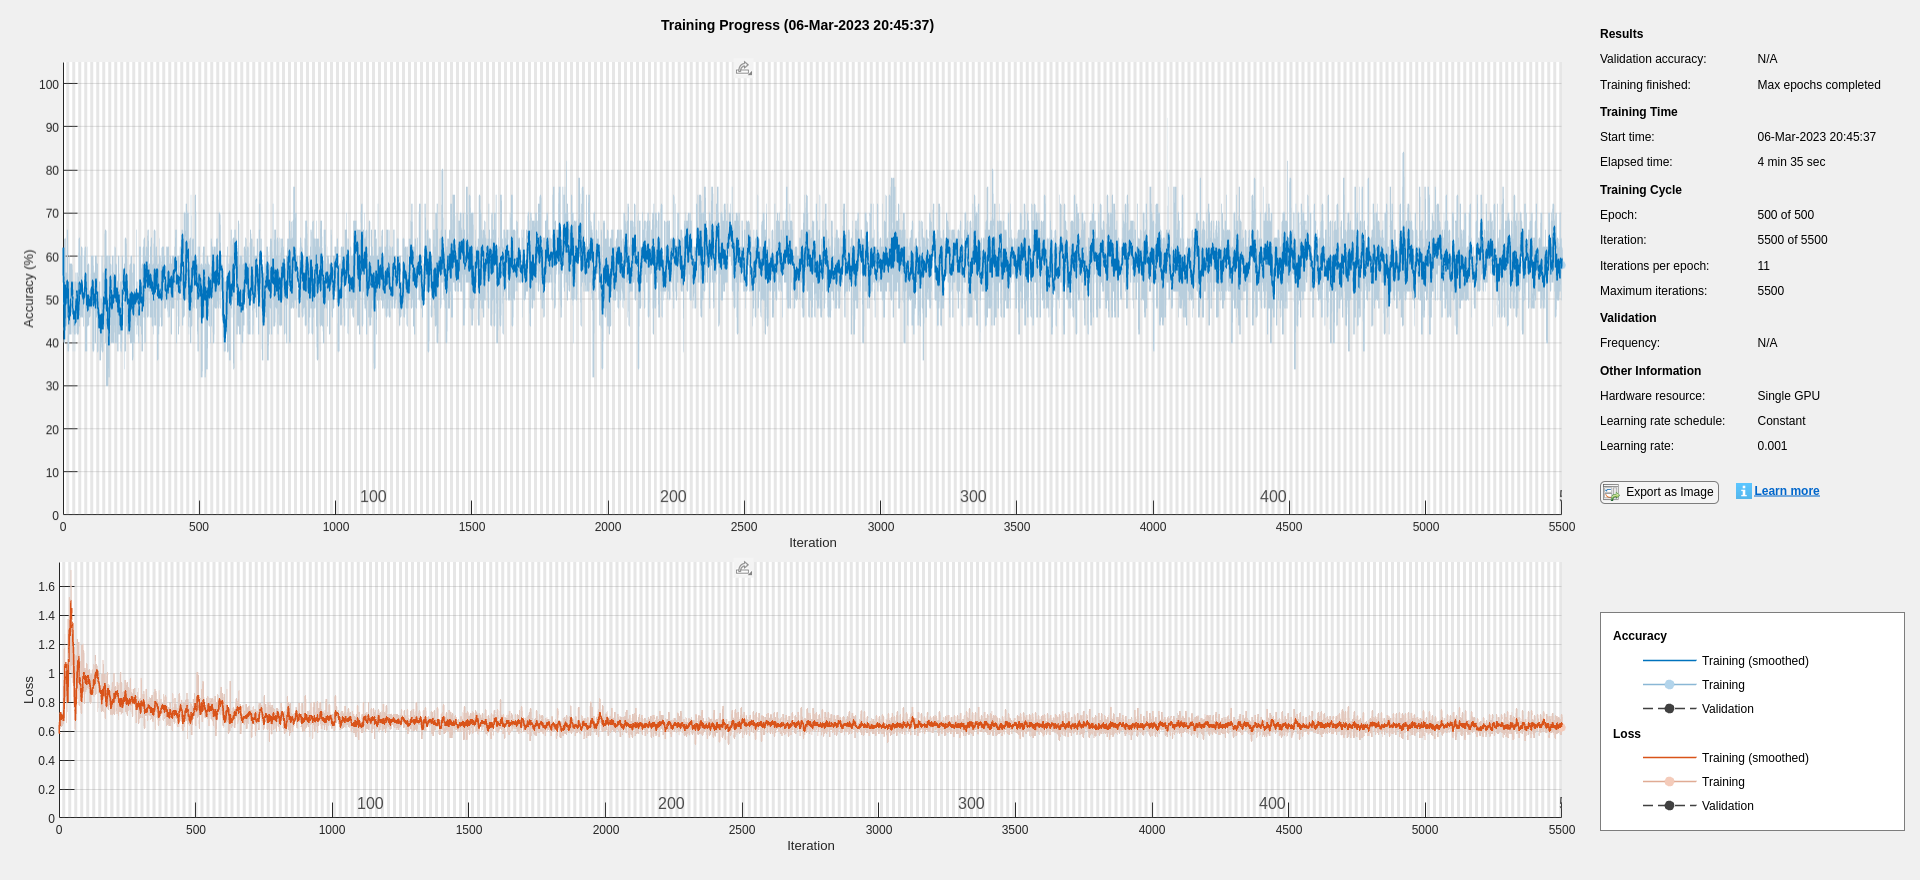

net = trainNetwork(InTrain,OutTrain,layerGraph(net),options);

save('net1.mat',"net");

## Test Model

Test the classification accuracy of the model by comparing the predictions on a held-out test set with the true labels for each time step. 

Use the trained network to make predictions by using the `classify` function.

OutPred = classify(net,InTest);

Visualize the predictions for **each sample** in a confusion matrix.

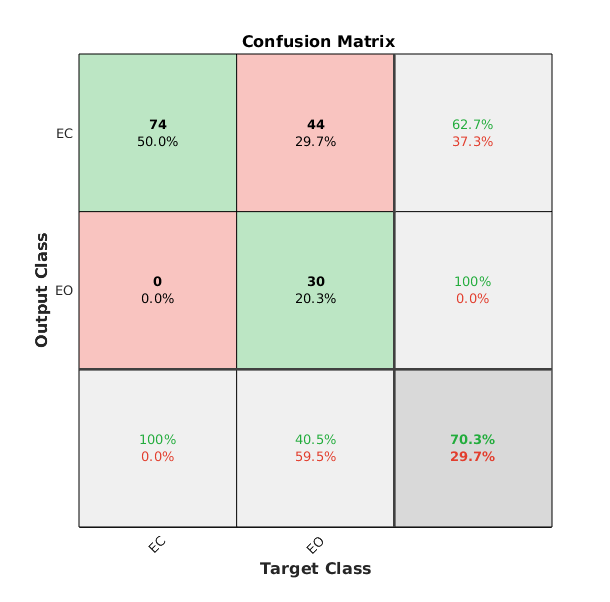

Pred = OutPred;
True = OutTest;
plotconfusion(True(:),Pred(:));

Visualize the predictions for **each sample** in a confusion matrix.

% Pred = vertcat(OutPred{:});
% True = vertcat(OutTest{:});
% PredCount = countcats(Pred');
% Predictions=1*(PredCount(1,:)<PredCount(2,:));
% PredChunk = categorical(Predictions,[0 1],{'EC', 'EO'});
% TrueChunk = True(:,1);
% plotconfusion(TrueChunk(:),PredChunk(:));